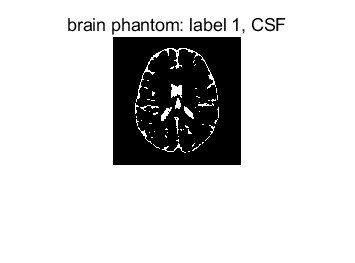

%% Computational MRI: Fall 2021
% Lab 1: Sequences and image contrast
% Part 2: T2 mapping
% florian.knoll@fau.de

clear all; close all; clc;

%% 1. McGill numerical phantom: Plot CSF, T1 and T2 regions, and display T1, T2, SD
% Aubert-Broche Neuroimage 2006
load digital_brain_phantom.mat;
[nR,nC,nSl] = size(ph.label);

% Plot regions
figure, imshow(ph.label == 1,[]); title('brain phantom: label 1, CSF'); 

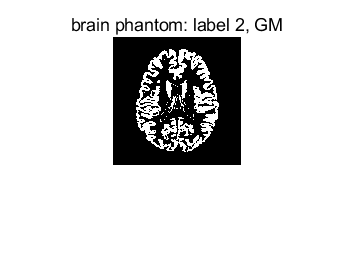

figure, imshow(ph.label == 2,[]); title('brain phantom: label 2, GM'); drawnow;

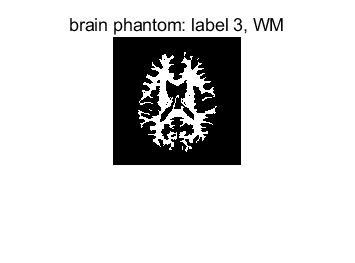

figure, imshow(ph.label == 3,[]); title('brain phantom: label 3, WM'); drawnow;


% Display T1, T2, SD
T1_csf = mean(ph.t1(ph.label == 1)); % Just use mean to select one element
T2_csf = mean(ph.t2(ph.label == 1));
SD_csf = mean(ph.sd(ph.label == 1));

disp(['T1 CSF = ', num2str(T1_csf), 'ms']);

T1 CSF = 2569ms


disp(['T2 CSF = ', num2str(T2_csf), 'ms']);

T2 CSF = 329ms


disp(['SD CSF = ', num2str(SD_csf)]);

SD CSF = 1



T1_gm = mean(ph.t1(ph.label == 2));
T2_gm = mean(ph.t2(ph.label == 2));
SD_gm = mean(ph.sd(ph.label == 2));

disp(['T1 GM = ', num2str(T1_gm), 'ms']);

T1 GM = 833ms


disp(['T2 GM = ', num2str(T2_gm), 'ms']);

T2 GM = 83ms


disp(['SD GM = ', num2str(SD_gm)]);

SD GM = 0.86



T1_wm = mean(ph.t1(ph.label == 3));
T2_wm = mean(ph.t2(ph.label == 3));
SD_wm = mean(ph.sd(ph.label == 3));

disp(['T1 WM = ', num2str(T1_wm), 'ms']);

T1 WM = 500ms


disp(['T2 WM = ', num2str(T2_wm), 'ms']);

T2 WM = 70ms


disp(['SD WM = ', num2str(SD_wm)]);

SD WM = 0.77


%%2.1 Simulate MR image contrast from pulse sequences
%M0 = ph.sd
%Proton density weighted (PDw), longTR, shortTE
TR = 12500

TR = 12500

TE = 5

TE = 5

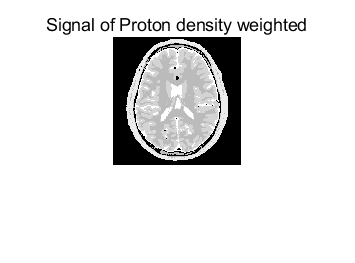

S = ph.sd.*(1-2*exp(-(TR-TE/2)./ph.t1) + exp(-TR./ph.t1)).*exp(-TE./ph.t2);
figure
imshow(S,[]); title('Signal of Proton density weighted'); 


%T1 weighted (T1w), shortTR, shortTE
TR = 500

TR = 500

TE = 10

TE = 10

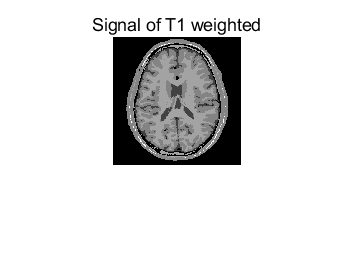

S = ph.sd.*(1-2*exp(-(TR-TE/2)./ph.t1) + exp(-TR./ph.t1)).*exp(-TE./ph.t2);
figure
imshow(S,[]); title('Signal of T1 weighted'); 


%T2 weighted (T2w), longTR, longTE
TR = 5000

TR = 5000

TE = 100

TE = 100

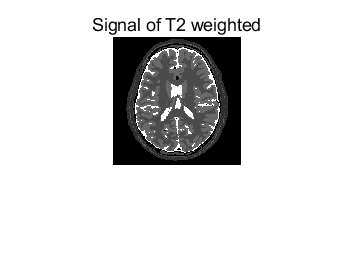

S = ph.sd.*(1-2*exp(-(TR-TE/2)./ph.t1) + exp(-TR./ph.t1)).*exp(-TE./ph.t2);
figure
imshow(S,[]); title('Signal of T2 weighted'); 

%%2.2 FLAIR sequence--T2-weighted-FLAIR
% matlab: .*pixel-wise multiply   * matrix multiply
% python: * pixel-wise multiply   .dot() matrix multiply
TR = 7000

TR = 7000

TE = 100

TE = 100

TI = log(2)*T1_csf

TI = 1.7807e+03

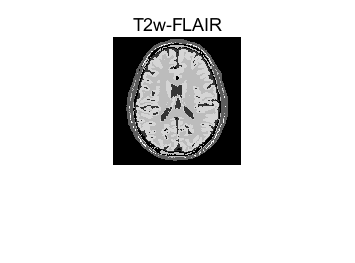

S = ph.sd.*(1-2*exp(-TI./ph.t1)+exp(-TR./ph.t1)).*exp(-TE./ph.t2);

figure
imshow(S,[]); title('T2w-FLAIR'); 

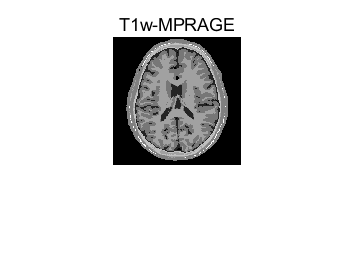

%%2.3 MPRAGE--T1-weighted-MPRAGE
% syms E1 E2 E3 E4 T1_star a

TR = 2420; TE = 3.68; TI = 960; 
ES = 10.2; %  time difference between excitation pulses
alpha = 9;
n1 = 80; % number of echo
N2D = 224; N3D = 160;
tao1 = TI - ES*n1;
tao2 = TR - tao1 -ES*N3D;
B1 = 1;
RP = 1; % receive sensitivity profile of  RF coil.
T1_star = 1./(1./ph.t1 - 1/ES*log(cos(alpha/180*pi*B1)));
E1 = exp(-tao1./ph.t1);
E2 = exp(-tao2./ph.t1);
E3 = exp(-(N3D*ES)./T1_star);
E4 = exp(-(n1*ES)./T1_star);
q1 = E4.*(1-2*E1+E1.*E2);
q2 = T1_star./ph.t1.*(1+E1.*E2.*E3-E1.*E2.*E4-E4);
q3 = (1+E1.*E2.*E3);
Q = (q1+q2)./q3;
S = ph.sd.*(sin(alpha/180*pi*B1)).*RP.*Q;

figure
imshow(S,[]); title('T1w-MPRAGE'); 

%%3.1 Add noise to the simulated data
kspace = fft2(ph.label)

kspace = 	1.0e+04 *

   3.4459 + 0.0000i  -1.0495 + 0.0458i  -0.6125 + 0.0158i  -0.3696 - 0.0578i  -0.1033 - 0.0194i   0.1952 + 0.0102i   0.2450 + 0.0079i   0.1258 + 0.0555i   0.0143 + 0.0156i  -0.1099 - 0.0562i  -0.0834 - 0.0169i  -0.0126 - 0.0096i   0.0184 + 0.0248i   0.0162 + 0.0227i  -0.0263 - 0.0061i  -0.0163 - 0.0182i   0.0221 - 0.0028i   0.0340 + 0.0021i   0.0401 + 0.0206i   0.0067 - 0.0016i  -0.0277 - 0.0081i  -0.0467 - 0.0190i  -0.0196 + 0.0169i  -0.0117 - 0.0080i   0.0308 + 0.0083i   0.0302 - 0.0016i   0.0031 + 0.0083i  -0.0035 - 0.0056i   0.0013 - 0.0098i  -0.0043 + 0.0022i  -0.0014 - 0.0002i  -0.0019 + 0.0186i  -0.0174 - 0.0053i  -0.0111 - 0.0079i  -0.0027 - 0.0052i   0.0146 - 0.0172i   0.0217 + 0.0200i   0.0163 + 0.0108i   0.0057 + 0.0077i  -0.0258 - 0.0140i  -0.0201 - 0.0079i  -0.0051 - 0.0051i   0.0012 + 0.0097i   0.0063 + 0.0095i   0.0099 - 0.0064i   0.0123 - 0.0015i  -0.0005 - 0.0054i  -0.0030 - 0.0127i   0.0027 + 0.0196i  -0.0077 + 0.0108i
  -0.3117 + 0.0460i  -0.4565

SNRdB = 50;
var_noise = norm(kspace,2)/10^(SNRdB/10)

var_noise = 0.4111


noise_real = normrnd(0,sqrt(var_noise),size(kspace,1),size(kspace,2))*mean(kspace(:))

noise_real = 	1.0e+-14 *

   0.0803 + 0.0009i   0.0280 + 0.0003i   0.1271 + 0.0015i   0.1204 + 0.0014i   0.0156 + 0.0002i  -0.0157 - 0.0002i  -0.0072 - 0.0001i  -0.0598 - 0.0007i  -0.0174 - 0.0002i   0.0112 + 0.0001i   0.0080 + 0.0001i   0.0927 + 0.0011i  -0.0525 - 0.0006i   0.0280 + 0.0003i   0.0520 + 0.0006i   0.1278 + 0.0015i   0.0625 + 0.0007i  -0.0688 - 0.0008i  -0.0644 - 0.0008i  -0.0171 - 0.0002i  -0.0749 - 0.0009i  -0.0676 - 0.0008i  -0.0993 - 0.0012i  -0.0180 - 0.0002i   0.0273 + 0.0003i   0.0862 + 0.0010i  -0.0520 - 0.0006i  -0.0394 - 0.0005i   0.0193 + 0.0002i   0.0026 + 0.0000i   0.0237 + 0.0003i  -0.0335 - 0.0004i  -0.0644 - 0.0008i  -0.1465 - 0.0017i   0.0018 + 0.0000i   0.0561 + 0.0007i  -0.0504 - 0.0006i   0.0110 + 0.0001i   0.0876 + 0.0010i  -0.0697 - 0.0008i   0.0104 + 0.0001i  -0.0307 - 0.0004i   0.0253 + 0.0003i  -0.0253 - 0.0003i  -0.0616 - 0.0007i   0.0113 + 0.0001i   0.0034 + 0.0000i  -0.0762 - 0.0009i  -0.0547 - 0.0006i  -0.1060 - 0.0012i
   0.0962 + 0.0011i  -0

noise_imag = normrnd(0,sqrt(var_noise),size(kspace,1),size(kspace,2))*mean(kspace(:))

noise_imag = 	1.0e+-14 *

   0.0809 + 0.0009i  -0.0554 - 0.0006i  -0.0530 - 0.0006i   0.0267 + 0.0003i   0.0358 + 0.0004i   0.1373 + 0.0016i  -0.0172 - 0.0002i   0.0235 + 0.0003i  -0.0777 - 0.0009i  -0.0470 - 0.0005i  -0.0520 - 0.0006i   0.0813 + 0.0009i   0.0464 + 0.0005i  -0.0964 - 0.0011i  -0.0404 - 0.0005i  -0.0202 - 0.0002i  -0.0035 - 0.0000i   0.1385 + 0.0016i   0.0435 + 0.0005i  -0.1595 - 0.0019i  -0.0325 - 0.0004i   0.0474 + 0.0006i  -0.0187 - 0.0002i  -0.0543 - 0.0006i  -0.0570 - 0.0007i  -0.0238 - 0.0003i  -0.0457 - 0.0005i  -0.1285 - 0.0015i   0.0047 + 0.0001i  -0.0336 - 0.0004i  -0.0717 - 0.0008i   0.0882 + 0.0010i  -0.0774 - 0.0009i  -0.0340 - 0.0004i   0.0034 + 0.0000i   0.0270 + 0.0003i   0.0516 + 0.0006i  -0.0148 - 0.0002i   0.0167 + 0.0002i   0.1225 + 0.0014i  -0.1123 - 0.0013i   0.0548 + 0.0006i   0.0273 + 0.0003i  -0.0812 - 0.0009i  -0.0124 - 0.0001i   0.0927 + 0.0011i   0.1154 + 0.0013i  -0.0764 - 0.0009i   0.0633 + 0.0007i   0.0740 + 0.0009i
   0.0396 + 0.0005i   0

kspace_noise = kspace + noise_real + noise_imag*1i;
noise_img = ifft2(kspace_noise)

noise_img =   -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i
  -0.0000 - 0.0000i  -0.0000 - 0.0000

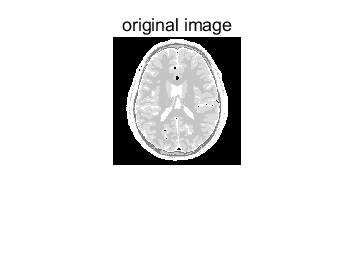


figure
imshow(ph.sd,[]); title('original image'); 

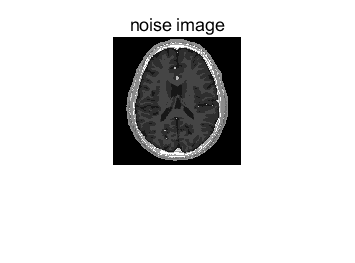

imshow(real(noise_img),[]); title('noise image'); 

%%3.2 T2 Mapping
T1_img = zeros(size(ph.label,1),size(ph.label,1))

T1_img =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

% S = zeros(10,size(ph.label,1),size(ph.label,1))
TE = linspace(100,300,11);
TR = 5000;

for i = 1:length(TE)
    Signal(i,:,:) = ph.sd.*(1-2*exp(-(TR-TE(i)/2)./ph.t1) + exp(-TR./ph.t1)).*exp(-TE(i)./ph.t2);
end

for i =1:size(ph.sd,1)
    for j =1:size(ph.sd,2)
        for img = 1:length(TE)
           y(img) = Signal(img,i,j);
        end
        x = TE;
        f{i,j} = fit(x(:), y(:), ft, 'StartPoint', [1 1]);

表达式无效。请检查缺失或多余的字符。

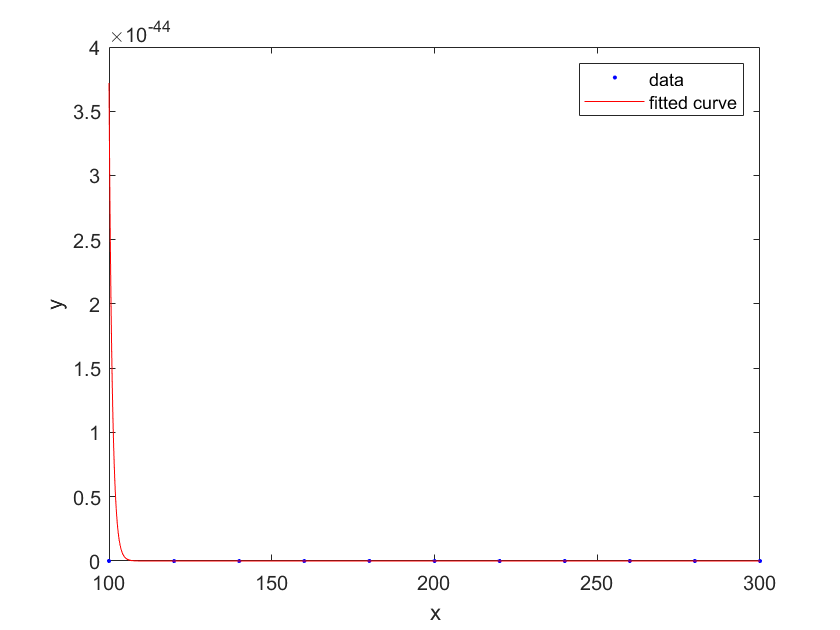

    end
end

